# Correct Data Lying on Ellipsoid

Generate uncalibrated magnetometer data lying on an ellipsoid.

c = [-50; 20; 100]; % Ellipsoid center
r = [30; 20; 50]; % Semiaxis radii

[x,y,z] = ellipsoid(c(1),c(2),c(3),r(1),r(2),r(3),20);
D = [x(:),y(:),z(:)];

Correct the magnetometer data so that it lies on a sphere. The option for the calibration is set by default to 'auto'.

[A,b,expmfs] = magcal(D); % Calibration coefficients
expmfs % Display the expected magnetic field strength in uT

expmfs = 31.0723

C = (D-b)*A; % Calibrated data

Visualize the uncalibrated and calibrated magnetometer data.

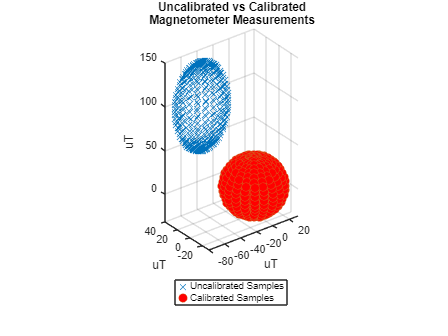

figure(1)
plot3(x(:),y(:),z(:),"LineStyle","none","Marker","X","MarkerSize",8)
hold on
grid(gca,"on")
plot3(C(:,1),C(:,2),C(:,3),"LineStyle","none","Marker","o", ...
      "MarkerSize",8,"MarkerFaceColor","r")
axis equal
xlabel("uT")
ylabel("uT")
zlabel("uT")
legend("Uncalibrated Samples","Calibrated Samples","Location","southoutside")
title("Uncalibrated vs Calibrated" + newline + "Magnetometer Measurements")
hold off

*Copyright 2018 The MathWorks, Inc.*